clear variables

syms R1 R2 L C1 C2 s H
A=[-(1/R1+1/R2)*1/C1 -1/(R1*C1);
             1/(R2*C2)    0];
b=[1/(R1*C1); 0];
c=[0 1];
d=0;
H=c*inv(s*eye(2)-A)*b+d

$$H = \frac{1}{C_{2}\,R_{1}\,s+C_{2}\,R_{2}\,s+C_{1}\,C_{2}\,R_{1}\,R_{2}\,s^{2}+1}$$

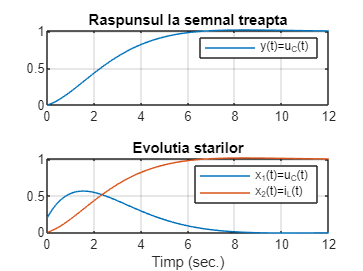


R1=1e3;
R2=47e2;
C1=13e-4;
C2=47e-5;
u=12;

% declare the state space object by callingss
sistem=ss([-(1/R1+1/R2)*1/C1 -1/(R1*C1); 1/(R2*C2) 0],[1/(R1*C1); 0],[0 1],0);

% initial conditions differentfrom zero
x0=[0.2 0];

% time simulation basis
t=0:0.1:12;

% unity step signal as input signal
u=ones(1,length(t));

% step response whencalling lsim
[y,t,x]=lsim(sistem,u,t,x0);

subplot(211); plot(t,y); title('Raspunsul la semnal treapta');
grid; 
legend('y(t)=u_C(t)')
subplot(212); plot(t,x);
title('Evolutia starilor');grid
xlabel('Timp (sec.)');
legend('x_1(t)=u_C(t)','x_2(t)=i_L(t)')